Q = [10, 4];
flow = 15;
fhigh = 120;
T = 2;
fs = 1000;
N = AudioDataConverter.L;
scat = Scattering(Q, T, fs, N, flow, fhigh);
figure
P = sum(abs(scat.filterBanks(1).Psi).^2, 1);
2/max(P)

ans =

    0.3857



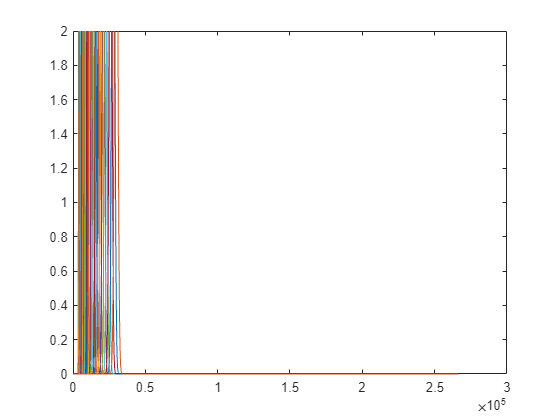

plot(abs(scat.filterBanks(1).Psi).^2')
ylim([0, 2])

sum(abs(scat.filterBanks(1).psi).^2, 2)

ans =     0.0053
    0.0057
    0.0061
    0.0065
    0.0070
    0.0075
    0.0081
    0.0086
    0.0093
    0.0099


scat.filterBanks(1).lambdas'

ans =    94.2478
  101.0123
  108.2623
  116.0326
  124.3607
  133.2865
  142.8529
  153.1060
  164.0949
  175.8726


scat.filterBanks(1).fc

ans =    15.0000   16.0766   17.2305   18.4672   19.7926   21.2132   22.7357   24.3676   26.1165   27.9910   30.0000   32.1532   34.4610   36.9343   39.5852   42.4264   45.4715   48.7351   52.2330   55.9820   60.0000   64.3064   68.9219   73.8687   79.1705   84.8528   90.9430   97.4703  104.4661  111.9640


max(scat.filterBanks(2).psiBWHz)

ans = 0.5946

scat.filterBanks(1).getSSamplingFreq()

ans = 2.0661

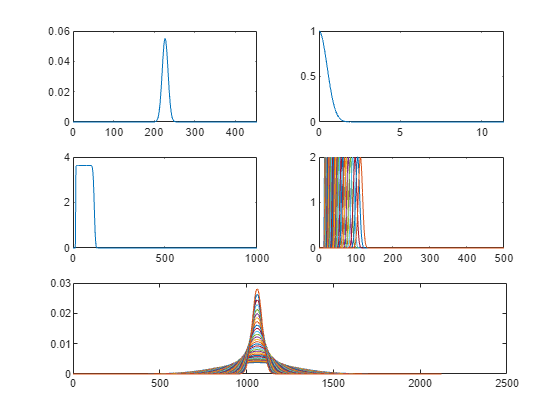

figure
scat.filterBanks(1).plot()

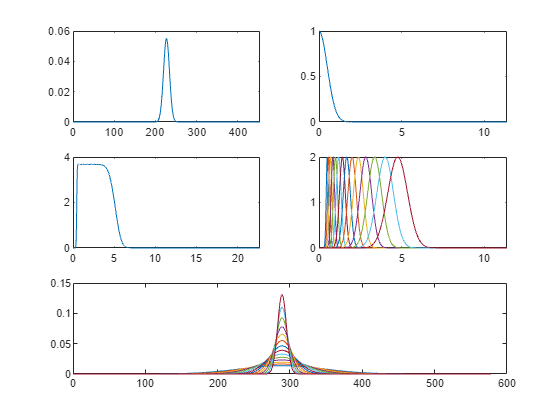

figure
scat.filterBanks(2).plot()

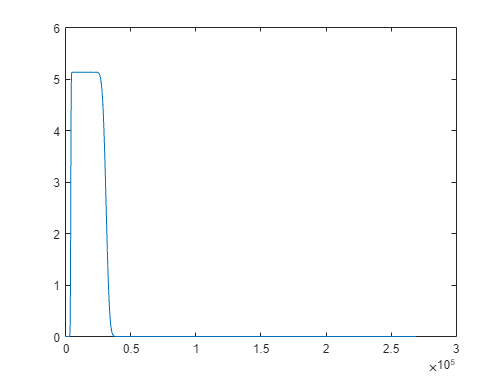

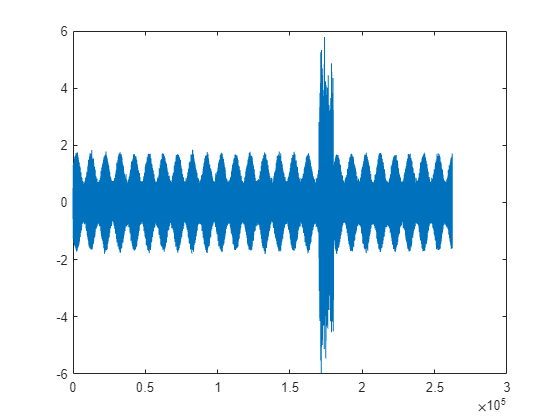

t = (0:N-1)/fs;
t = t';
x = randn(N, 1)*0.1;
f0 = 60.*(t < 100) + 30.*(t > 100) + 45*sin(2*pi*0.05*t).*(t < 50) + 5*sin(2*pi*0.8*t).*(t > 150 & t < 200) + 5*sin(2*pi*1.5*t).*(t > 200) + 2*sin(2*pi*1*t).*(t < 100 & t > 50);
f0 = cumsum(f0/fs);
y = sin(2*pi*f0) .* (1 + 0.5*sin(2 * pi * t * 0.1));
x = x + bandpass(randn(N, 1)*4 .* (t < 180 & t > 170), [25, 80], fs);

plot(x+y);

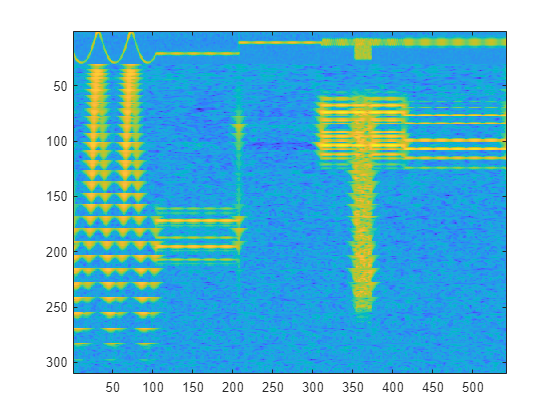

coeffs = scat.scattering(x+y);
figure
imagesc(log(coeffs./prctile(coeffs, 20, 2)))

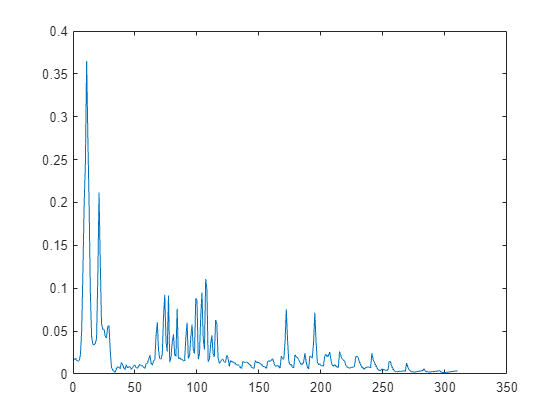

% set(gca, "YDir", "normal")
figure
plot(mean(coeffs, 2))

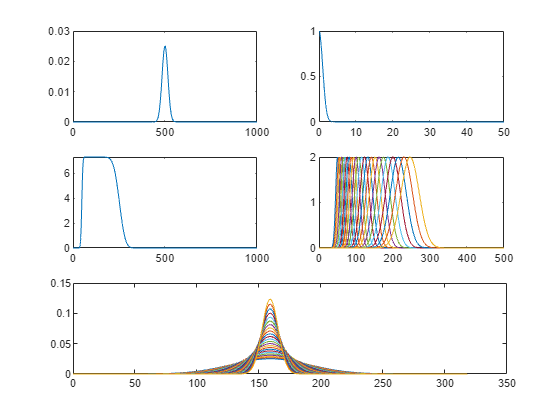

N = 200000;
w = randn(N,1);
scat = Scattering(10, 1, 1000, N, 50, 250);
scat.filterBanks(1).plot()

coeffs = scat.scattering(w);
mean(coeffs.^2, 2)./(scat.filterBanks(1).lambdas')

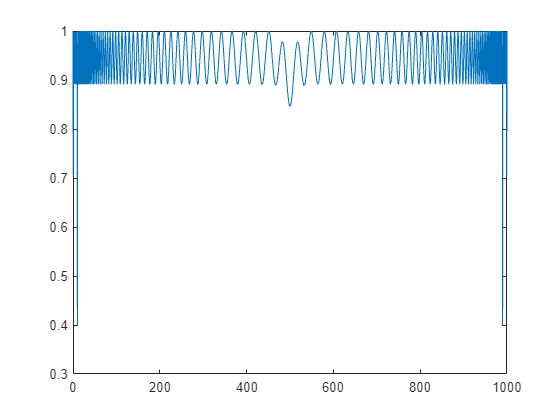

sf = waveletScattering('QualityFactors',Q,...
    'SamplingFrequency',fs, 'SignalLength', N, 'InvarianceScale',2, 'OptimizePath',false);
[lpsum,f] = littlewoodPaleySum(sf);
plot(f,lpsum(:,1))

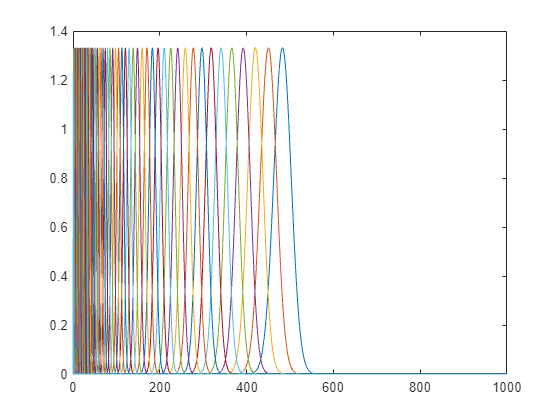

[filters,f] = filterbank(sf);
figure
plot(f,filters{2}.psift)

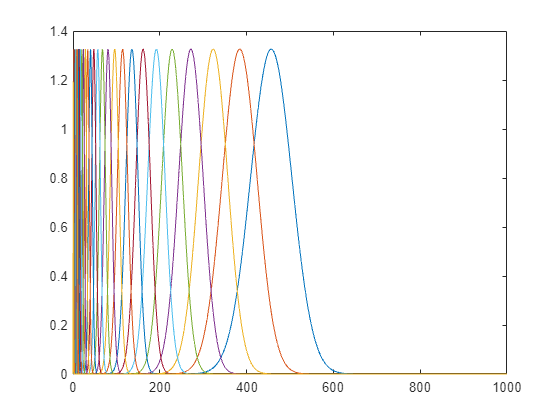

figure
plot(f,filters{3}.psift)

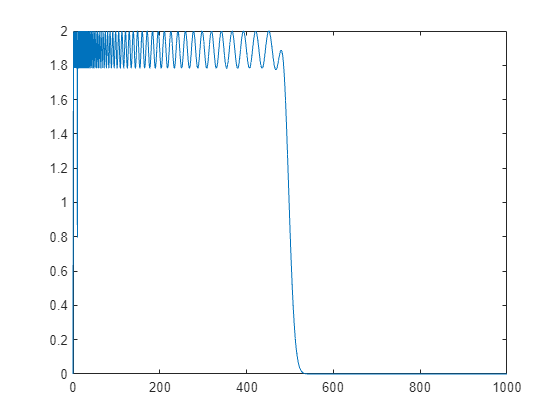

plot(f,sum(filters{2}.psift.^2, 2))

max(sum(filters{2}.psift, 2))/max(P)

ans =

    0.3885



[M, u] = featureMatrix(sf, single(x));
% [s, u] = scatteringTransform(sf,x)